## Very much copied from F&I homework 4

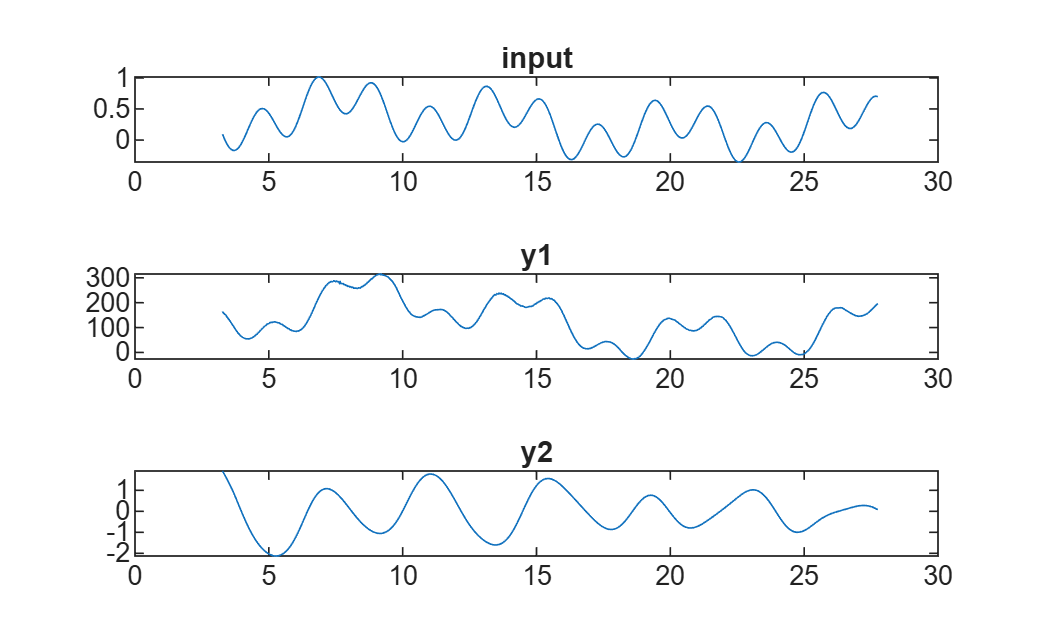

l = 2; % number of outputs
N = size(t,2);
end_train = floor(N*2/3);
y = zeros(N*2,1);

% forming "joint" output vector
for i = 1:N
    y(2*(i-1)+1:2*i) = [y1(i); y2(i)]; % y(i) = [y1(i); y2(i)];
end

y_train = y(1:l*end_train);
u_train = u(1:end_train);
t_train = t(1:end_train);

figure; 
tiledlayout(3,1);

nexttile;
plot(t_train,u_train);
title("input");

nexttile;
plot(t_train,y_train(1:2:end));
title("y1");

nexttile;
plot(t_train, y_train(2:2:end));
title("y2");

## Hankel Matrices

s = 100;
N = length(u_train) - 2*s + 1;
Up = zeros(s,N);
Yp = zeros(l*s,N);
Uf = zeros(s,N);
Yf = zeros(l*s,N);

for i = 1:N
    Up(:,i) = u_train(i:i+s-1);
    Yp(:, i) = y_train(l*(i-1)+1:l*(s+i)-l);
    
    Uf(:,i) = u_train(i+s:i+2*s-1);
    Yf(:,i) = y_train(l*(i-1)+1+l*s:l*(2*s+i)-l);
end

## L_32 + model order

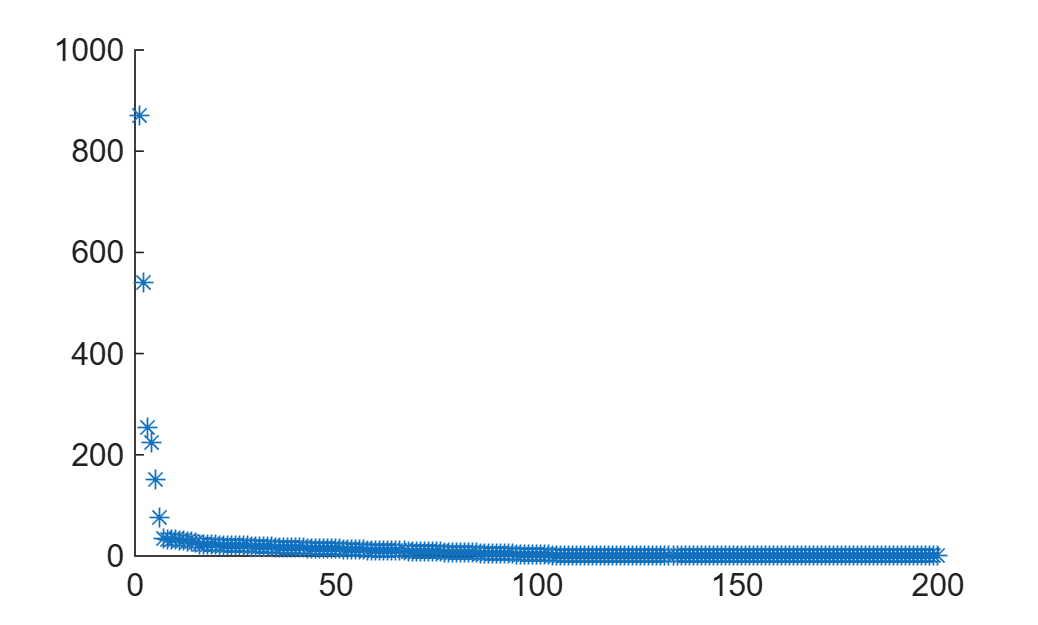

in_mat = [Uf ; Up ; Yp ; Yf];
[~,R] = qr(in_mat');
L = R(1:600, 1:600)';
L_32 = L((l+2)*s+1 : (2+2*l)*s, s+1 : (2+l)*s);

[U,S,~] = svd(L_32, "vector");
figure;
scatter(1:2*s, S, '*');

## Computing system matrices

n = 3;
U1 = U(:, 1:n);
C = U1(1:l,:);
A = U(1:l*(s-1), 1:n) \ U(l+1:l*s, 1:n);

N = length(u_train);

phi = zeros(l*N, n+n+l);
phi1 = C;
phi2 = zeros(l,n);
phi3 = kron(u_train(1), eye(l));
phi(1:2,:) = [phi1 phi2 phi3];

for k = 2:N
    phi1 = phi1 * A;
    phi2 = zeros(size(phi2));
    for tau = 1 : k-1
        phi2 = phi2 + u_train(tau) * C*A^(k-tau-1);
    end
    phi3 = kron(u_train(k), eye(l));
    phi((k-1)*2+1:2*k, :) = [phi1 phi2 phi3];
end

output = phi \ y_train(1:N*l, 1);
x0 = output(1:n);
B = output(n+1:2*n);
D = output(2*n+1:end);

## Something else

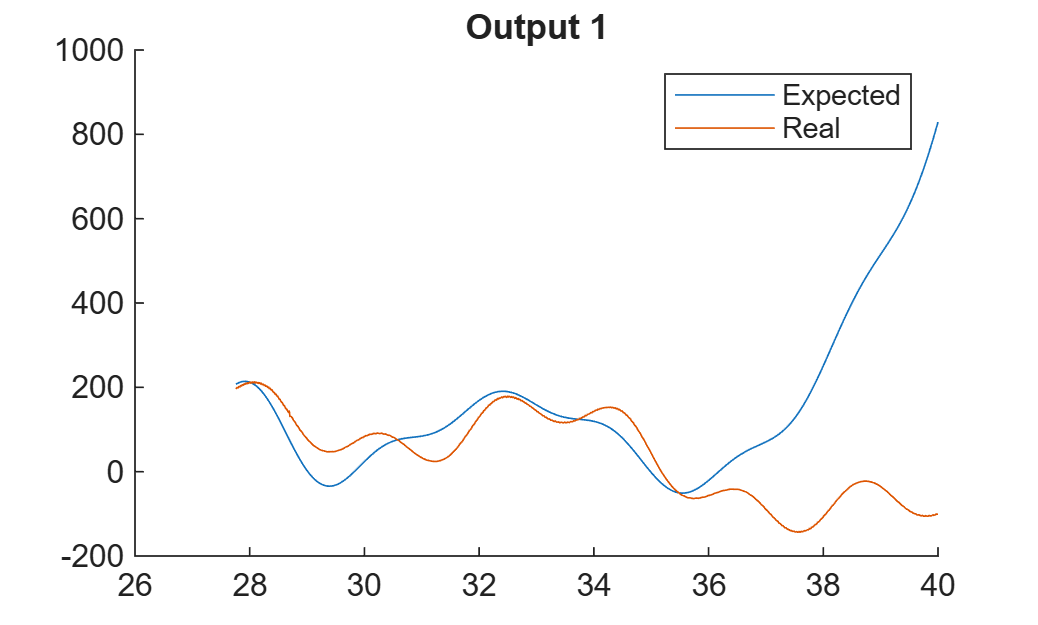

% for funky signal
[y,~] = simsystem(A,B,C,D,x0,u(end_train+1:end)); % [y,x]

figure;
hold on
plot(t(end_train+1:end),y(1,:))
plot(t(end_train+1:end),y1(end_train+1:end))
title("Output 1");
legend("Expected", "Real");

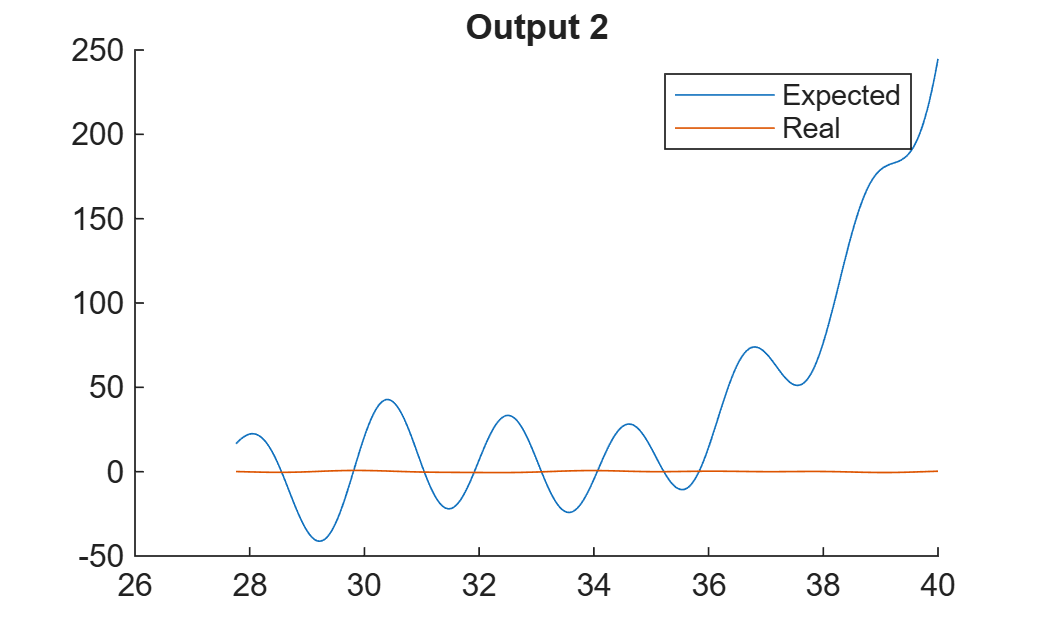


figure;
hold on 
plot(t(end_train+1:end),y(2,:))
plot(t(end_train+1:end),y2(end_train+1:end))
title("Output 2");
legend("Expected", "Real");